## What direction does the mouse turn the wheel? 

Let's assign a turning direction for each trial. 

data = readtable('data_active_pos_fb.xml');

An indicator of turning direction maybe the average turning velocity. 

The direction is estimated by the sign of the average (<0 -> left turn , >0 -> right turn)

mean_turn_vels = mean( data.wheel_speed, 2);
% equivalent 
mean_turn_vels = mean( data.wheel_speed')';

data.mean_wheel = mean_turn_vels;

#### Visualise average turning velocities

plot(data{data.mean_wheel>0, 'wheel_speed'}')

plot first 10 trials with mean velocity greater than 0 

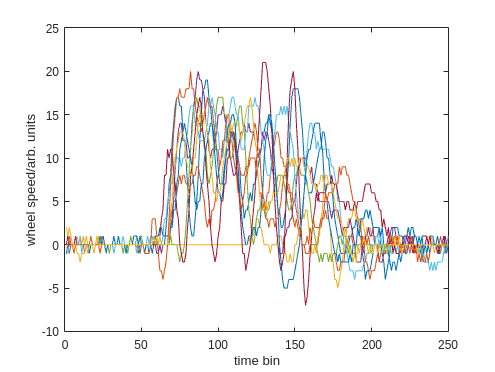

dd= data(data.mean_wheel>0, 'wheel_speed');
plot(dd{1:10, 'wheel_speed'}')
xlabel('time bin')
ylabel('wheel speed/arb. units')

Looks like average velocity could be reasonable indicator. Now plot all trials

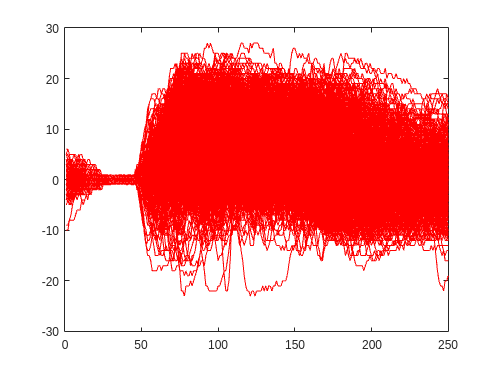

plot(data{data.mean_wheel>0, 'wheel_speed'}', 'Color','r')

Overplotting is an issue. Plot instead a datashader type figure 

data_ = data(1:100,:); % limit to first 100 rows of table 
yy =flip([-30:29]'); % REMOVE HARDCODING

ss =size(data_.wheel_speed);
res =zeros([length(yy),ss(2)]);

for i=1:ss(2)
    [n, edges]= histcounts(data_.wheel_speed(:,i),[-30:30]);% REMOVE HARDCODING
    res(:,i) = n';
end
res = flip(res);

plot as heatmap

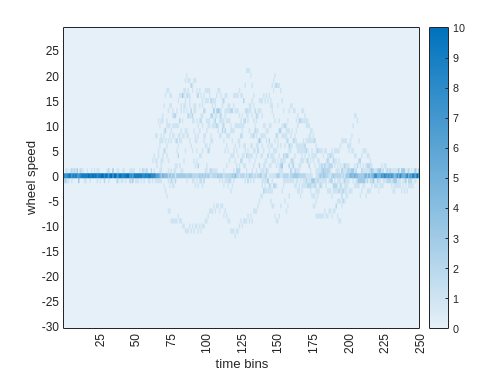

h = heatmap(res,"ColorMethod","none");

grid off

%format y axis
YLabels =yy;
CustomYLabels = string(YLabels);
CustomYLabels(mod(YLabels,5) ~= 0) = " ";
h.YDisplayLabels = CustomYLabels;
ylabel('wheel speed')

%format x axis
XLabels = [1:ss(2)];
CustomXLabels = string(XLabels);
CustomXLabels(mod(XLabels,25) ~= 0) = " ";
h.XDisplayLabels = CustomXLabels;
xlabel('time bins')

Plot as image (better as colorscale can be set to logarithmic)

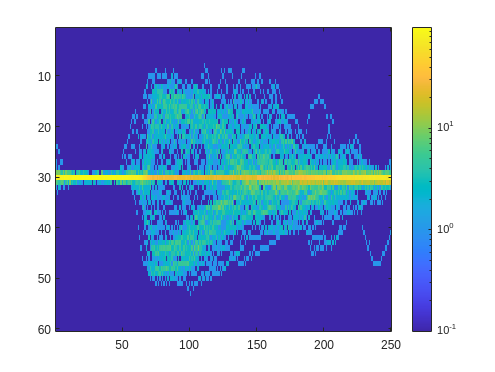

im=image(res,'CDataMapping','scaled');
colorbar
set(gca,'ColorScale','log')


% add axis labels

CustomXLabels = 1×250 string array
    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    "25"    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    "50"    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    "75"    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    "100"    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    "125"    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " "    " 